clear;

p11 = [262;207;1]; p12 = [204;148;1];
p21 = [395;124;1]; p22 = [396;217;1];
p31 = [424;235;1]; p32 = [330;336;1];
p41 = [307;324;1]; p42 = [184;270;1];
p51 = [168;168;1]; p52 = [290;101;1];
p61 = [290;95;1]; p62 = [424; 156; 1];
p71 = [338;210;1]; p72 = [392;255;1];
p81 = [210;268;1]; p82 = [258;195;1];

m_left = zeros(3,8);
m_right = zeros(3,8);

m_left(:,1) = project_point_left(p11);
m_left(:,2) = project_point_left(p21);
m_left(:,3) = project_point_left(p31);
m_left(:,4) = project_point_left(p41);
m_left(:,5) = project_point_left(p51);
m_left(:,6) = project_point_left(p61);
m_left(:,7) = project_point_left(p71);
m_left(:,8) = project_point_left(p81);

m_right(:,1) = project_point_right(p12);
m_right(:,2) = project_point_right(p22);
m_right(:,3) = project_point_right(p32);
m_right(:,4) = project_point_right(p42);
m_right(:,5) = project_point_right(p52);
m_right(:,6) = project_point_right(p62);
m_right(:,7) = project_point_right(p72);
m_right(:,8) = project_point_right(p82);

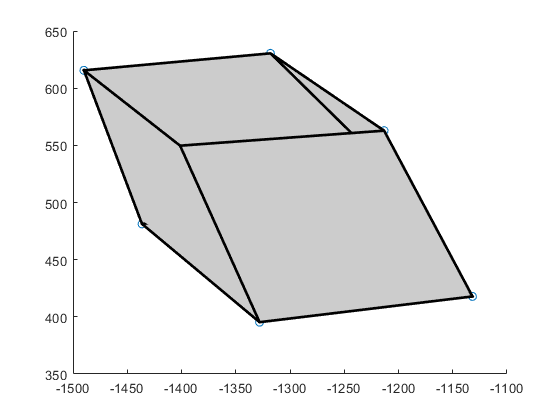

output_vid = VideoWriter('output.avi');
open(output_vid);

O1 = [-1535.21;1720.84;1693.22];
O2 = [-1694.56;-142.25;1585.19];

s = apply_view_point(O1, O2, m_left, m_right);
record_plot(output_vid, s);

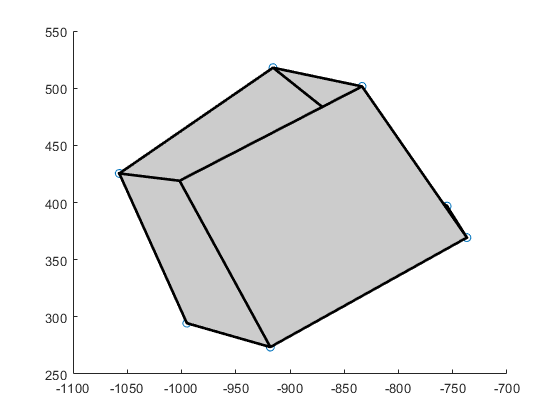


O1 = [-1200; 1520; 1700];
O2 = [-1820; -200; 1000];

s = apply_view_point(O1, O2, m_left, m_right);
record_plot(output_vid, s);

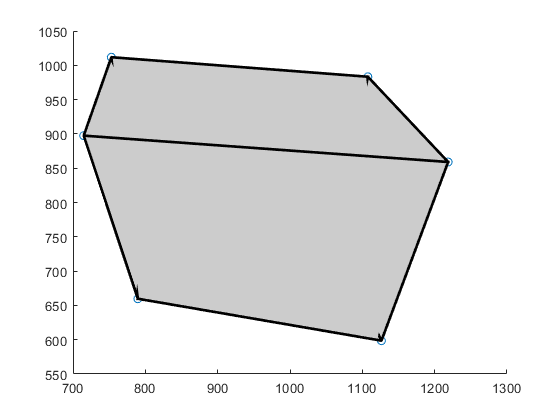


O1 = [1200; 1520; 1100];
O2 = [-1120; -200; 1000];

s = apply_view_point(O1, O2, m_left, m_right);
record_plot(output_vid, s);

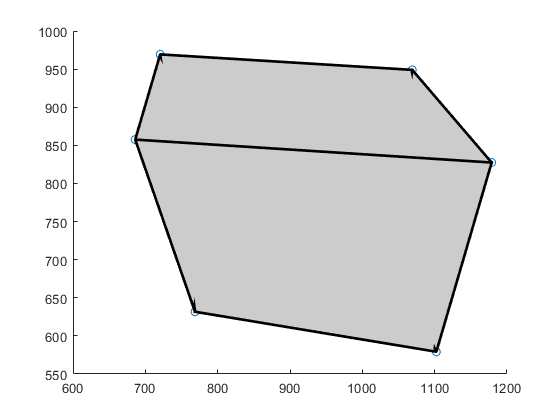


O1 = [1200; 1420; 1000];
O2 = [-1050; -200; 1000];

s = apply_view_point(O1, O2, m_left, m_right);
record_plot(output_vid, s);

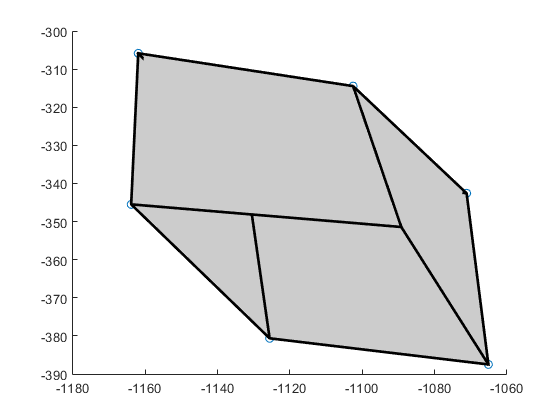


O1 = [-1200; 0; 1100];
O2 = [-1120; -500; 1070];

s = apply_view_point(O1, O2, m_left, m_right);
record_plot(output_vid, s);

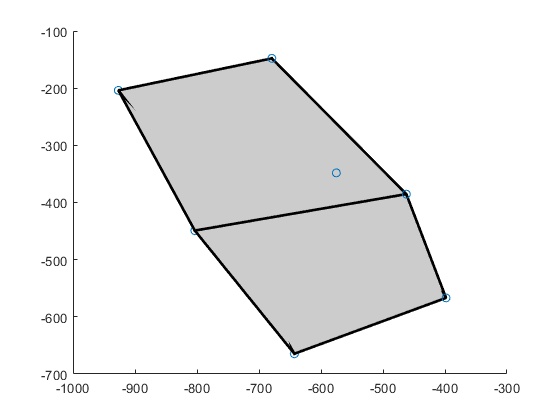


O1 = [-1000; 0; 700];
O2 = [1120; -100; 1070];

s = apply_view_point(O1, O2, m_left, m_right);
record_plot(output_vid, s);


close(output_vid);
disp("Video created in the current working directory.")

Video created in the current working directory.


# External Functions

function M = project_point_left(m)

Pc = [1 0 0 0; 0 1 0 0; 0 0 1 0];

alpha_u=779.36; alpha_v=752;
A = [alpha_u 0 320; 0 alpha_v 240; 0 0 1];

T = [-1535.21; 1720.84; 1693.22];
omega=-35.16; phi=-46.77; kappa=-155.57;
R = [cos(kappa) sin(kappa) 0; -sin(kappa) cos(kappa) 0; 0 0 1]...
    * [cos(phi) 0 -sin(phi); 0 1 0; sin(phi) 0 cos(phi)]...
    * [1 0 0; 0 cos(omega) sin(omega); 0 -sin(omega) cos(omega)];
D = [R T; 0 0 0 1];

P = A*Pc*D;
P = P(:,1:end-1);
M = P\m;

end

function M = project_point_right(m)

Pc = [1 0 0 0; 0 1 0 0; 0 0 1 0];

alpha_u=779.36; alpha_v=752;
A = [alpha_u 0 320; 0 alpha_v 240; 0 0 1];

T = [-1694.56; -142.25; 1585.19];
omega=25.03; phi=-55.56; kappa=-47.08;
R = [cos(kappa) sin(kappa) 0; -sin(kappa) cos(kappa) 0; 0 0 1]...
    * [cos(phi) 0 -sin(phi); 0 1 0; sin(phi) 0 cos(phi)]...
    * [1 0 0; 0 cos(omega) sin(omega); 0 -sin(omega) cos(omega)];
D = [R T; 0 0 0 1];

P = A*Pc*D;
P = P(:,1:end-1);
M = P\m;

end

function P = reconstruct_point(p1, p2, o1, o2)

I = eye(3);
P = pinv((I - p1*p1') + (I - p2*p2'))...
    * (o1 + o2 - (o1'*p1)*p1 - (o2'*p2)*p2);

end

function s = apply_view_point(O1, O2, m_left, m_right)

P1 = reconstruct_point(m_left(:,1),m_right(:,1),O1,O2);
P2 = reconstruct_point(m_left(:,2),m_right(:,2),O1,O2);
P3 = reconstruct_point(m_left(:,3),m_right(:,3),O1,O2);
P4 = reconstruct_point(m_left(:,4),m_right(:,4),O1,O2);
P5 = reconstruct_point(m_left(:,5),m_right(:,5),O1,O2);
P6 = reconstruct_point(m_left(:,6),m_right(:,6),O1,O2);
P7 = reconstruct_point(m_left(:,7),m_right(:,7),O1,O2);
P8 = reconstruct_point(m_left(:,8),m_right(:,8),O1,O2);

figure;
s = scatter([P1(1),P2(1),P3(1),P4(1),P5(1),P6(1),P7(1),P8(1)], [P1(2),P2(2),P3(2),P4(2),P5(2),P6(2),P7(2),P8(2)]);

draw_surface(P1,P2,P3,P4);
draw_surface(P5,P6,P7,P8);
draw_surface(P1,P5,P6,P2);
draw_surface(P3,P4,P8,P7);

end

function draw_surface(p1,p2,p3,p4)

P = [p1,p2,p3,p4]';
X = P(:,1); Y=P(:,2); Z=P(:,3);
patch('XData',X,'YData',Y,'ZData',Z,'EdgeColor','black','FaceColor',[.8 .8 .8],'LineWidth',2);

end

function record_plot(vid, plot)

fps = 30;

saveas(plot,'plot.png');

for i=1:fps
    writeVideo(vid, imread('plot.png'));
end

delete 'plot.png'

end